# ARbot_Rev2_1 ik Verification

Create a generalized inverse kinematics solver that holds a robotic arm at a specific location and points toward the robot base. Create the constraint objects to pass the necessary constraint parameters into the solver.

Load predefined ARbot robot model, which is specified as a `rigidBodyTree` object.

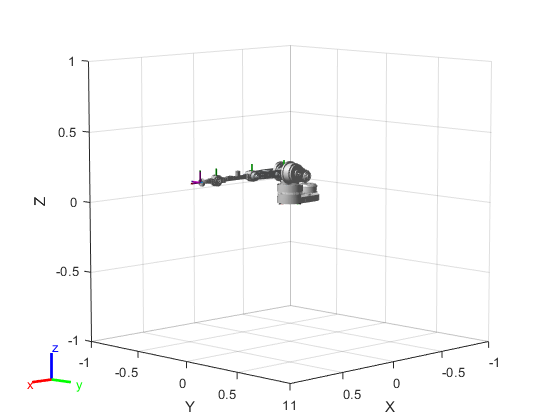

close all
robot=importrobot('Arbot_Rev2_1.urdf');
% Add gravity
gravityVec = [0 0 -9.80665];
robot.Gravity = gravityVec; 

% Add another massless coordinate frame for the end effector

eeOffset = 0.150;
eeBody = robotics.RigidBody('end_effector');
eeBody.Mass = 0;
eeBody.Inertia = [0 0 0 0 0 0];
setFixedTransform(eeBody.Joint,trvec2tform([eeOffset 0 0]));
figure(1);
addBody(robot,eeBody,'L4');
axes=show(robot); 
axes.CameraPositionMode = 'auto';

## Load Key Waypoints

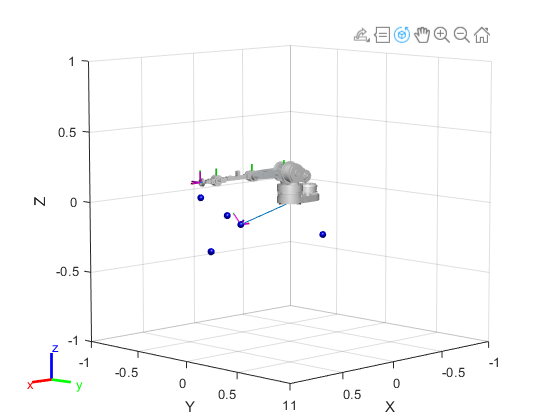



% NOT FLIPPED X AND Y TO ACCOUNT FOR MATLAB REFERENCE FRAME
P_A_BORG_65 = [ 0.2205 0.5588 -0.3135];
P_A_BORG_75 = [0.5024 0.5588 -0.2109];
P_A_BORG_8 = [0.6434 0.5588 -0.1596];
P_A_BORG_9 = [0.9253 0.5588 -0.0570];

% FLIP X AND Y TO ACCOUNT FOR MATLAB REFERENCE FRAME
P_A_BORG_65 = [ -0.5588 -0.2205 -0.3135];
P_A_BORG_75= [-0.5588 -0.5024 -0.2109]; % 2nd furthest 9.75
P_A_BORG_8 = [ -0.5588; -0.6434; -0.1596 ]; % furthest from the robot 9.8
P_A_BORG_9 = [ -0.5588; -0.9253; -0.0570 ]; % furthest from the robot 9.9

% corners for the end point

%% 75
P_B = [ 0; 0; 0; 1;];
T_A_B(1:3,1:3) = [   0.0000    0.9397   -0.3420;
                   -1.0000    0.0000         0;
                         0    0.3420    0.9397;];
T_A_B(1:3,4) = P_A_BORG_75;
P_A = T_A_B * P_B; % vector from the base of the robot to the target
% get joint angles for each point
P_end = P_A;
P_end(1) = -P_end(1);
P_mid_75 = midpoint(P_A,P_end);

%% 8
P_B = [ 0; 0; 0; 1;];
T_A_B(1:3,1:3) = [   0.0000    0.9397   -0.3420;
                   -1.0000    0.0000         0;
                         0    0.3420    0.9397;];
T_A_B(1:3,4) = P_A_BORG_8;
P_A = T_A_B * P_B; % vector from the base of the robot to the target
% get joint angles for each point
P_end = P_A;
P_end(1) = -P_end(1);
P_mid_8 = midpoint(P_A,P_end);

%% 9
P_B = [ 0; 0; 0; 1;];
T_A_B(1:3,1:3) = [   0.0000    0.9397   -0.3420;
                   -1.0000    0.0000         0;
                         0    0.3420    0.9397;];
T_A_B(1:3,4) = P_A_BORG_9;
P_A = T_A_B * P_B; % vector from the base of the robot to the target

% get joint angles for each point
P_end = P_A;
P_end(1) = -P_end(1);
P_mid_9 = midpoint(P_A,P_end);
%%



angleInRadians = deg2rad(-70);
wayPoints = [ P_A_BORG_65(1) P_A_BORG_65(2) P_A_BORG_65(3);
   -P_A_BORG_65(1) P_A_BORG_65(2) P_A_BORG_65(3);   
      P_mid_75;
      P_mid_8;
      P_mid_9;] ;
  
body = rigidBody('targetFrame');

ROTX = rotx(20);
ROTZ = rotz(180);

tform = trvec2tform(wayPoints(3,:));
tform(1:3,1:3) = tform(1:3,1:3) * ROTZ * ROTX ;
setFixedTransform(body.Joint,tform)
addBody(robot, body, robot.BaseName);


show(robot,robot.homeConfiguration);
exampleHelperPlotWaypoints(wayPoints)

hold on

Create the System object™ for solving generalized inverse kinematics.

gik = generalizedInverseKinematics;

Configure the System object to use the KUKA robot robot.

gik.RigidBodyTree = robot;

Tell the solver to expect a `PositionTarget` object and a `constraintAiming` and `constraintPositionTarget` object as the constraint inputs.

gik.ConstraintInputs = {'position','aiming'};

Create the two constraint objects.

- The origin of the body named `tool0` is located at `[0.0 0.5 0.5]` relative to the robot's base frame.

- The *z*-axis of the body named `tool0` points toward the origin of the robot's base frame.

gripper = 'end_effector'

gripper = 'end_effector'

posTgt = constraintPositionTarget(gripper);
posTgt.TargetPosition = P_mid_75;

aimCon = constraintAiming(gripper);
aimCon.TargetPoint = P_mid_75;
%aimCon.ReferenceBody = 'targetFrame';
% aimCon.TargetPoint = [ 0 0 1 ];

Find a configuration that satisfies the constraints. You must pass the constraint objects into the System object in the order in which they were specified in the `ConstraintInputs` property. Specify an initial guess at the robot configuration.

q0 = homeConfiguration(robot); % Initial guess for solver
[q,solutionInfo] = gik(q0,posTgt,aimCon);

Visualize the configuration returned by the solver.

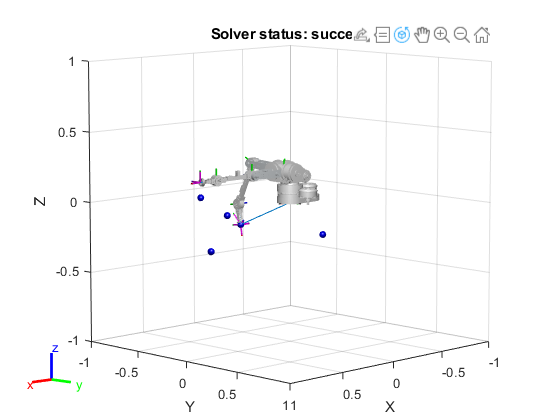

show(robot,q);
title(['Solver status: ' solutionInfo.Status])

## Repeat For All wayPoints

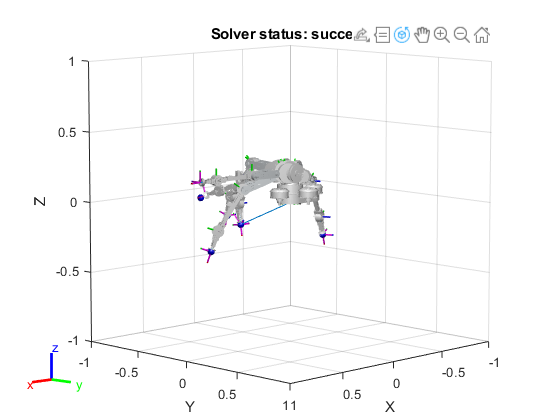


for i = 1:length(wayPoints)
    posTgt = constraintPositionTarget(gripper);
    posTgt.TargetPosition = wayPoints(i,:);
    
    aimCon = constraintAiming(gripper);
    aimCon.TargetPoint = wayPoints(i,:);
    q0 = homeConfiguration(robot); % Initial guess for solver
    [q,solutionInfo] = gik(q0,posTgt,aimCon);
    show(robot,q, 'PreservePlot', true,'Frames','on');
end

## Visualize potential workspaces

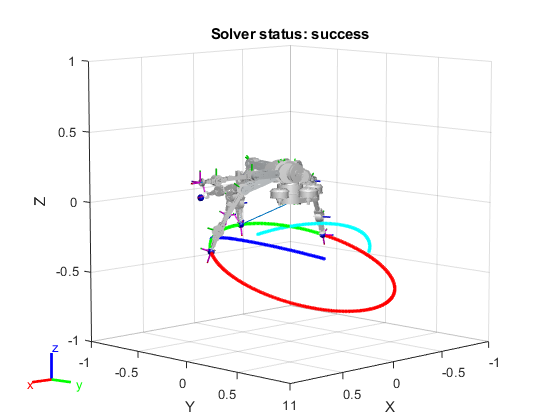

%% fit and plot

[center,rad,v1,v2] = circlefit3d(wayPoints(1,:),wayPoints(2,:),wayPoints(3,:));
idx = 1;
for i=1:1:361
    a = i/180*pi;
    x = center(:,1)+sin(a)*rad.*v1(:,1)+cos(a)*rad.*v2(:,1);
    y = center(:,2)+sin(a)*rad.*v1(:,2)+cos(a)*rad.*v2(:,2);
    z = center(:,3)+sin(a)*rad.*v1(:,3)+cos(a)*rad.*v2(:,3);
    workspace_points(idx,:) = [ x y z 1] ;
    plot3(x,y,z,'r.');
    idx = idx + 1;
end

%% filter workspace to relevant parts
indices_of_workspace = find(workspace_points(:,3)>wayPoints(1,3));
filtered_workspace = workspace_points(indices_of_workspace,:);
filtered_workspace = sortrows(filtered_workspace);
for i=1:length(indices_of_workspace)
    a = i/180*pi;
    x = filtered_workspace(i,1);
    y = filtered_workspace(i,2);
    z = filtered_workspace(i,3);
    plot3(x,y,z,'g.');
    pause(0.01);
    idx = idx + 1;
end
hold on
%% convert points from world to robot POV

corrected_workspace(:,1) = filtered_workspace(:,2);
corrected_workspace(:,2) = filtered_workspace(:,1);
corrected_workspace(:,3) = filtered_workspace(:,3);
% points are now corrected, to be in the robot POV

for i=1:length(indices_of_workspace)
    a = i/180*pi;
    x = corrected_workspace(i,1);
    y = corrected_workspace(i,2);
    z = corrected_workspace(i,3);
    plot3(x,y,z,'c.');
    pause(0.01);
    idx = idx + 1;
end

%% plot filtered (in front of robot)
P_A_BORG = [[0];[0];[0];]; % middle catch line, use 
P_B = [];
P_A = [];
for i=1:length(filtered_workspace)
    P_B(i,:) = [ filtered_workspace(i,1) filtered_workspace(i,2) filtered_workspace(i,3) 1];
    T_A_B(1:3,1:3) = rotz(90);
    T_A_B(1:3,4) = P_A_BORG;
    P_A(i,:) = T_A_B * P_B(i,:).';
end

for i=1:length(P_A)
    x = P_A(i,1);
    y = P_A(i,2);
    z = P_A(i,3);
    plot3(x,y,z,'b.');
    pause(0.01);
end

## Solve all IK angles and Visualize

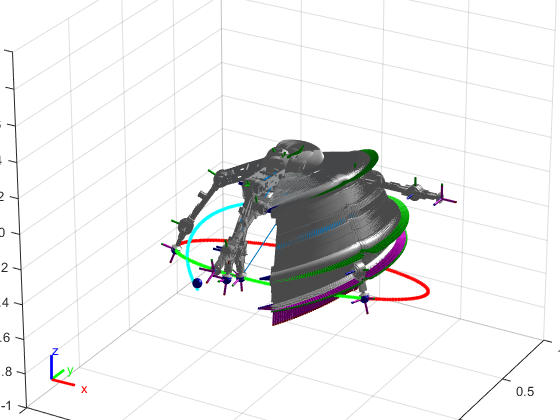

figure(1)
ikLookup = [];
for i = 1:size(P_A,1)
    posTgt = constraintPositionTarget(gripper);
    posTgt.TargetPosition = P_A(i,1:3);
    aimCon = constraintAiming(gripper);
    aimCon.TargetPoint = P_A(i,1:3);
    q0 = homeConfiguration(robot); % Initial guess for solver
    [q,solutionInfo] = gik(q0,posTgt,aimCon);
    
    ikLookup(i,1) = q(1).JointPosition;
    ikLookup(i,2) = q(2).JointPosition;
    ikLookup(i,3) = q(3).JointPosition;
    ikLookup(i,4) = q(4).JointPosition;
    show(robot,q, 'PreservePlot', true,'Frames','on');
    hold on
    % pause(0.01);
    % robot.plot(theta(idx));
end
hold off

## Save all workspace variables

save('ikLookupIterative.mat','ikLookup');
save('ARbot_workspace_iterative.mat','P_A');

## Helper Functions

function rot_z = rotz(ang)
    rot_z = [ cosd(ang) -sind(ang) 0;
                sind(ang) cosd(ang) 0 ;
                0 0 1;];
end

function rot_x = rotx(ang)
        rot_x = [ 1 0 0;
        0 cosd(ang) -sind(ang);
        0 sin(ang) cos(ang);];
end

function P_mid = midpoint(P1,P2)
    P_mid(1) = (P1(1) + P2(1)) / 2;
    P_mid(2) = (P1(2) + P2(2)) / 2;
    P_mid(3) = (P1(3) + P2(3)) / 2;
end

*Copyright 2019 The MathWorks, Inc.*